# **基于亮点模型的潜艇回波仿真**

***参考文献:***

***基于亮点模型的潜艇回波仿真  何心怡 蒋兴舟 林建域***

***一种基于亮点模型的潜艇回波仿真  董仲臣 ,李亚安,陈 晓***

clc;clear;close all;

## 1.仿真发射信号

信号的包络是一个梯形

信号的参数

%入射角
theta = 45;
% 定义时间参数
fs = 20e3;
t = 0:1/fs:20 - 1/fs; % 时间向量，这里生成0到20秒的时间序列，采样间隔为1/fs
N = length(t);
f = -fs/2:fs/N:fs/2-fs/N;
Ts = 1/fs;
fc = 5e3;
c = 1500;
% 定义梯形脉冲参数
Am = 1; % 幅度为1V
%总脉宽120ms，上升10ms，下降10ms
width = 100e-3; % 宽度为100ms
rise_time = 10e-3; % 上升时间设为10ms
fall_time = 10e-3; % 下降时间设为10ms

生成包络

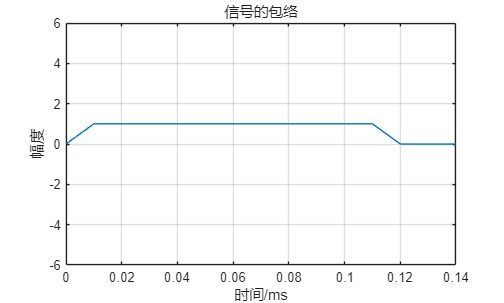

 a = zeros(size(t));
%生成梯形脉冲
for i = 1:length(t)
    if t(i) >= 0 && t(i) < rise_time
        a(i) = Am * t(i) / rise_time;
    elseif t(i) >= rise_time && t(i) < rise_time + width
        a(i) = Am;
    elseif t(i) >= rise_time + width && t(i) < rise_time + width + fall_time
        a(i) = Am - Am * (t(i) - (rise_time + width))/fall_time;
    end
end
%绘制梯形脉冲信号
figure;
plot(t, a);
xlabel('时间/ms');ylabel('幅度');title('信号的包络');
grid on;
axis([0,0.14,-6,6]);

发射的窄带脉冲

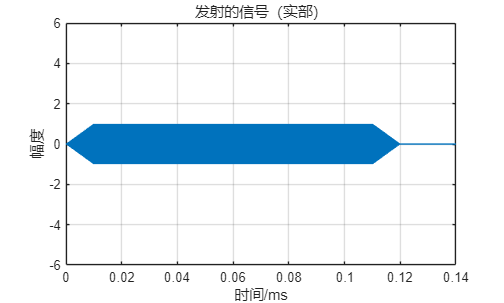

wc = 2*pi*fc;
P = a.*exp(j*wc*t);
figure;
plot(t, real(P));
xlabel('时间/ms');ylabel('幅度');title('发射的信号（实部）');
grid on;
axis([0,0.14,-6,6]);

## 2.多普勒频移

潜艇运动产生的多普勒频移：

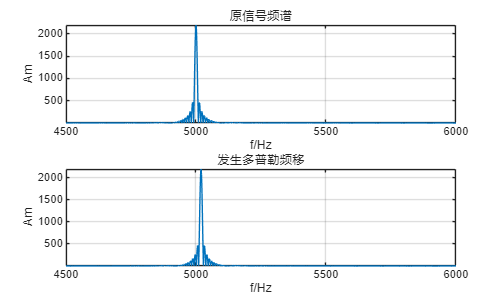

v = 4.112;%潜艇运动速度8海里/h      0.514*8
wd = 2*wc*v*cos(theta*pi/180)/c;%多普勒角频率

PWithDoplar = P.*exp(1j*wd*t);
figure
subplot(2,1,1)
plot(f,abs(fftshift(fft(P))));xlabel('f/Hz');ylabel('Am');title('原信号频谱');grid on;
axis([4500,6000,-inf,inf]);
subplot(2,1,2)
plot(f,abs(fftshift(fft(PWithDoplar))));xlabel('f/Hz');ylabel('Am');title('发生多普勒频移');grid on;
axis([4500,6000,-inf,inf]);

P = PWithDoplar;%变量替换

## 3.使用Bellhop计算脉冲响应（修改中）

### 仿真深海场景

### 声速梯度

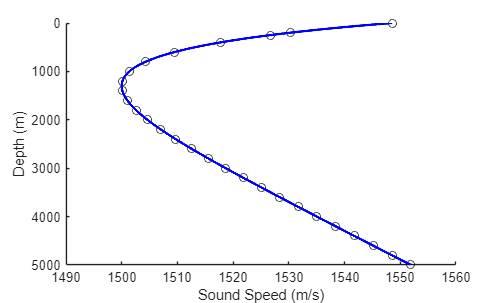

__________________________________________________________________
Munk profile, coherent
Frequency = 5000 Hz 
Number of media = 1 

    Spline approximation to SSP
    Attenuation units: dB/wavelength
    VACUUM

     z (m)     alphaR (m/s)      betaR       rho (g/cm^3)    alphaI        betaI 
    ( Number of pts = 51  Roughness =   0.00  Depth =  5000.00 ) 
      0.00       1548.52          0.00          1.00        0.0000        0.0000 
    200.00       1530.29          0.00          1.00        0.0000        0.0000 
    250.00       1526.69          0.00          1.00        0.0000        0.0000 
    400.00       1517.78          0.00          1.00        0.0000        0.0000 
    600.00       1509.49          0.00          1.00        0.0000        0.0000 
    800.00       1504.30          0.00          1.00        0.0000        0.0000 
   1000.00       1501.38          0.00          1.00        0.0000        0.0000 
   1200.00       1500.14          0.00          1.00        0.00

figure; 
bellhop testEnvs\MunkB_Coh;clc;
plotssp('testEnvs\MunkB_Coh');

根据梯度图，当声源为1000m深时，声速时1500m/s

### 脉冲响应

bellhop计算脉冲响应

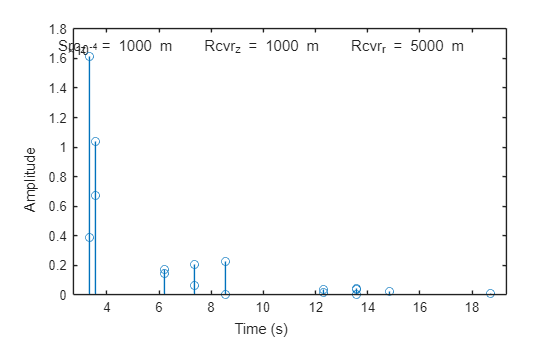

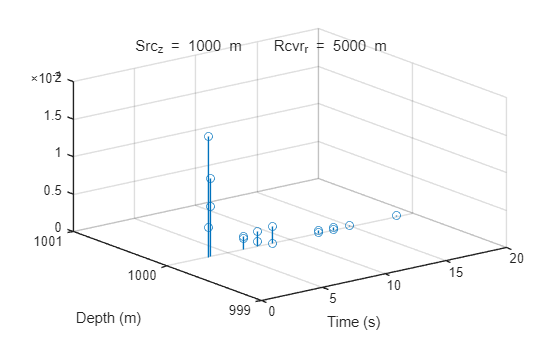

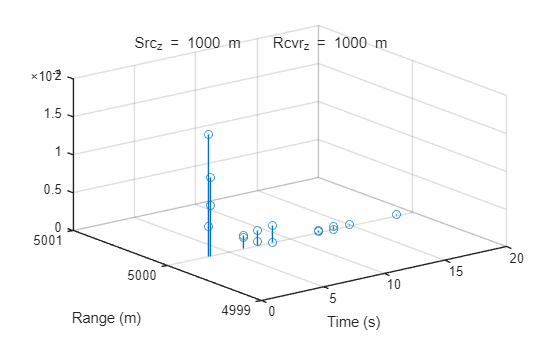

bellhop ('testEnvs\MunkB_Arr');
figure
plotarr('testEnvs\MunkB_Arr.arr',1,1,1);grid on;

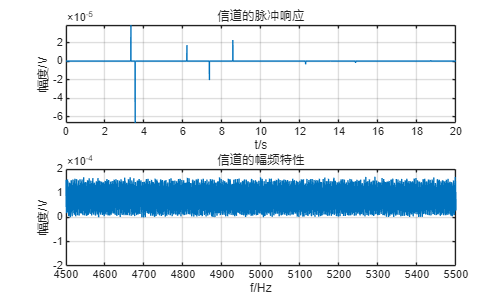

[ Arr, Pos ] = read_arrivals_asc( 'testEnvs\MunkB_Arr.arr' );
Amp = real(Arr.A);%到达幅度
delay = Arr.delay;%到达时延


Amp_Delay = [delay;Amp];
Amp_Delay(:,all(Amp_Delay==0,1))=[]; %去掉0值
Amp_Delay=sortrows(Amp_Delay',1);  %按照时延从小到大排序
% figure
% stem(Amp_Delay(:,1),Amp_Delay(:,2));

t = 0:1/fs:20 - 1/fs; % 时间向量，这里生成0到0.14秒的时间序列，采样间隔为1/fs
IR = zeros(1,length(t));
%将bellhop得到的序列插入进单位脉冲响应中
delayIndex = round(Amp_Delay(:,1)./Ts);
for i = 1:length(delayIndex)
    IR(delayIndex(i)) = Amp_Delay(i,2);
end
TF1 = fftshift(fft(IR));
f = -fs/2:fs/N:fs/2-fs/N;
figure
subplot(2,1,1)
plot(t,IR);xlabel('t/s');ylabel('幅度/V');grid on;
axis([0,20,-inf,inf]);title('信道的脉冲响应');
subplot(2,1,2)
plot(f,abs(TF1));xlabel('f/Hz');ylabel('幅度/V');grid on;
axis([4500,5500,-20e-5,20e-5]);title('信道的幅频特性');

信号经过信道

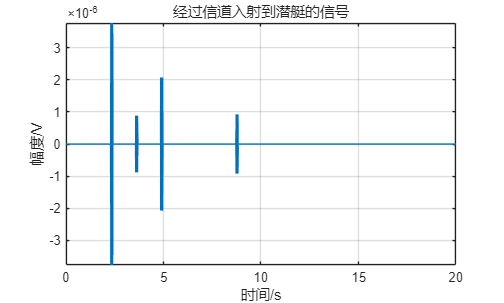

PAfterChan = conv(real(IR),P,'same');
figure
plot(t,real(PAfterChan));xlabel('时间/s');ylabel('幅度/V');grid on;
title('经过信道入射到潜艇的信号');axis([0,20,-inf,inf]);

P = PAfterChan;

## 4.每个亮点的时延

R为鱼雷与潜艇距离,即鱼雷与代表艇尾的亮点距离;0为照射角;表示该亮点与艇艉的距离

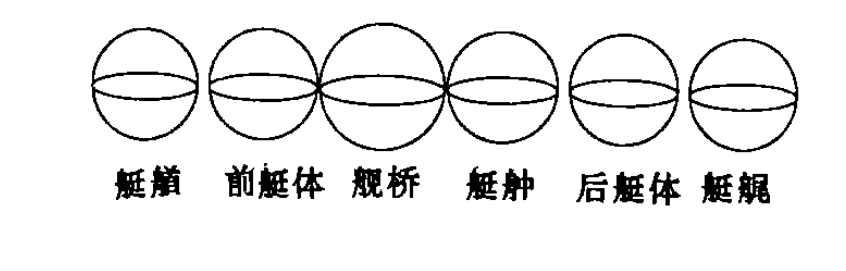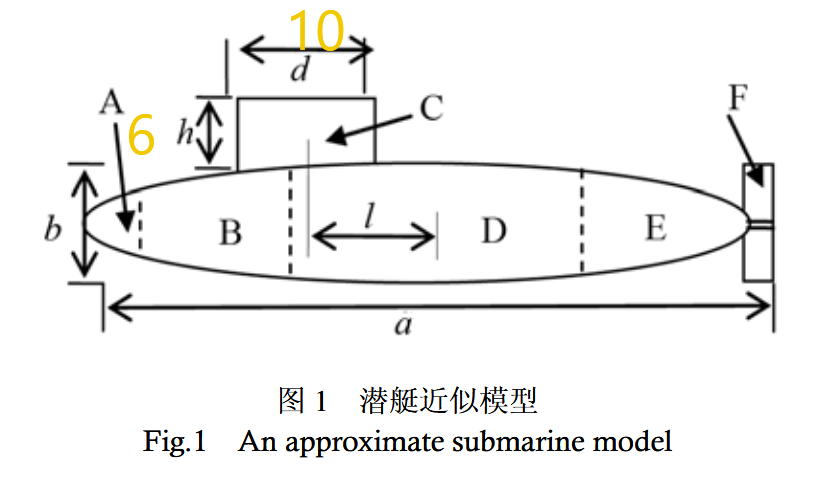

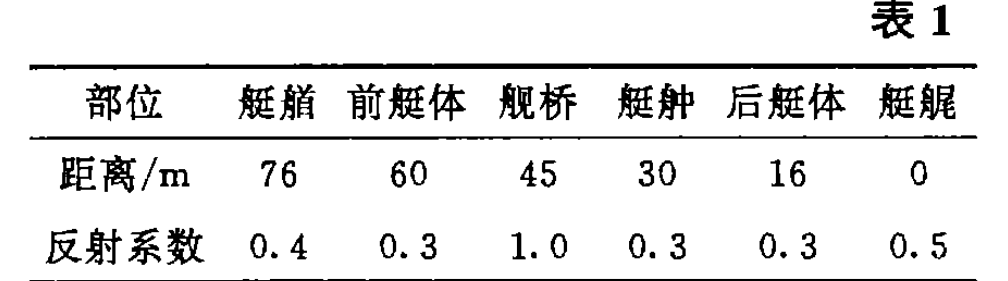

tauHighLight = zeros(6,1);
L = zeros(6,1);  %L存放亮点与艇艇的距离
L = [76,   60,     45,   30,   16,   0]; 
R = 5000;    %两者的距离5km
c = 1500;    %深度1000m 声速1500m/s

 % for j = 1:6
 %      term1 = (R + L(j)*cos(theta*pi/180)).^2;
 %      term2 = (L(j)*sin(theta*pi/180))^2;
 %      numerator = 2*sqrt(term1 + term2);
 %      tau(j) = numerator/c;
 % end

for j = 1:6
     term1 = (L(j)*cos(theta*pi/180)).^2;
     term2 = (L(j)*sin(theta*pi/180))^2;
     numerator = 2*sqrt(term1 + term2);
      tauHighLight(j) = numerator/c;  %此时c为1500m/s 深度1000m
end

亮点的时延

for i = 1:6 
    fprintf('%f s\n', tauHighLight(i));
end

0.101333 s
0.080000 s
0.060000 s
0.040000 s
0.021333 s
0.000000 s


## 5.计算亮点的子回波幅度

计算每个亮点的半径（这里数据不全）

% 定义距离和反射系数
b = [0.4, 0.3, 1.0, 0.3, 0.3, 0.5];
r = [7,7,8,7,7,7];

### 计算隐蔽系数

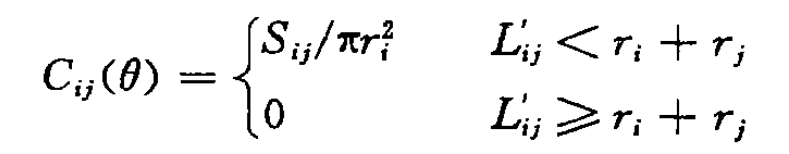

计算Sij

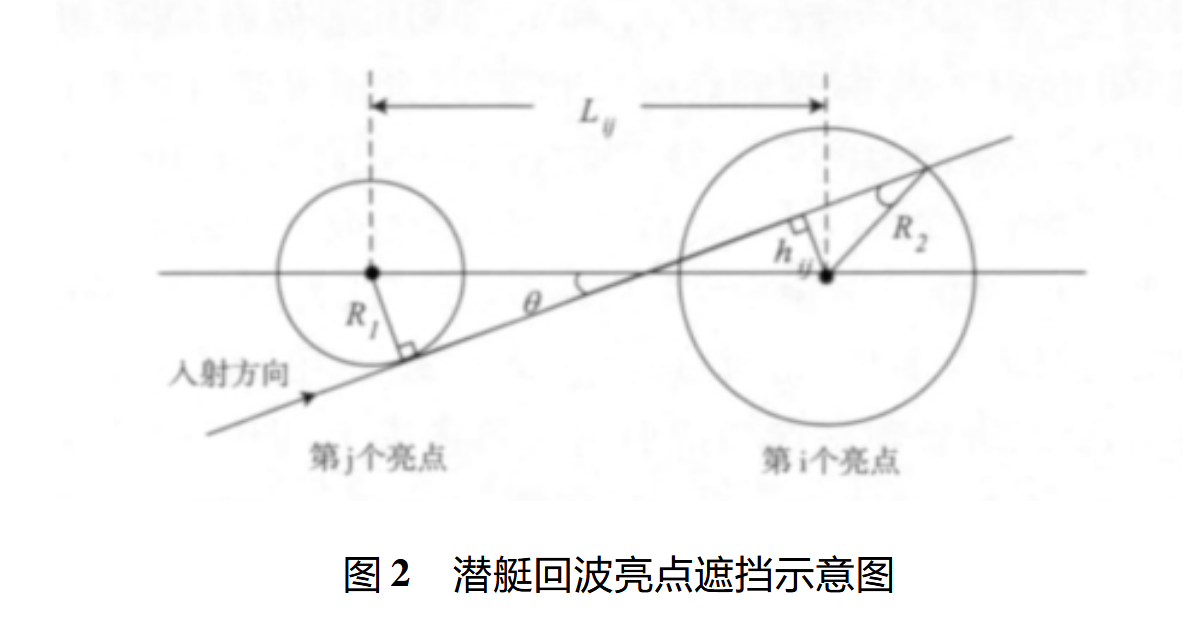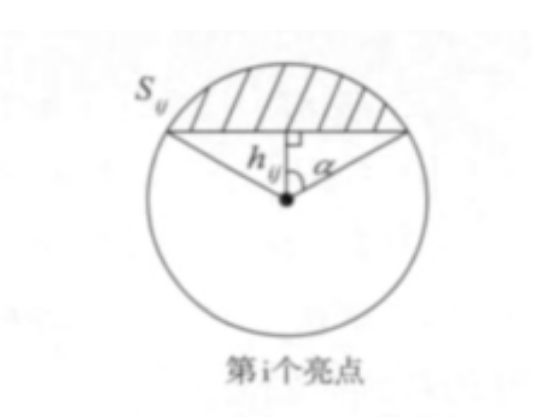

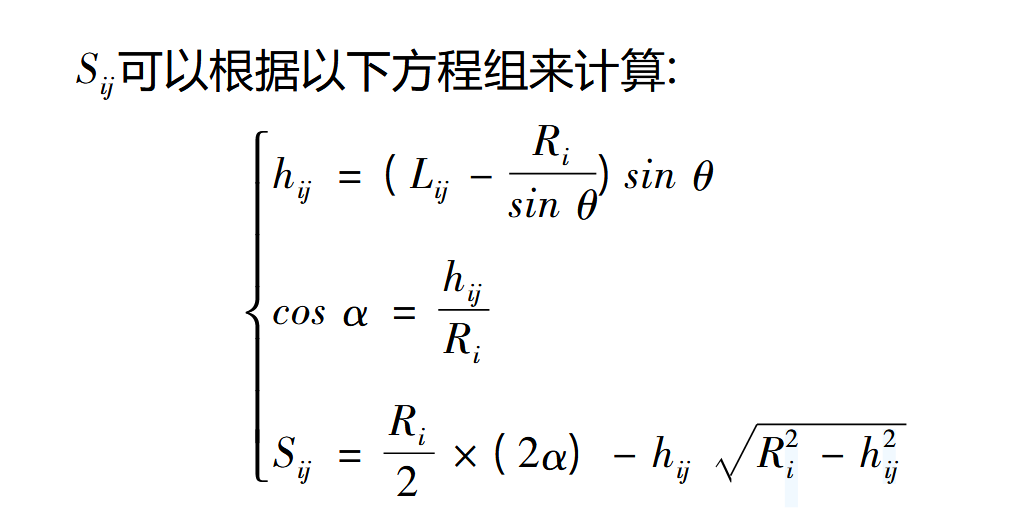

L_ij = zeros(6,6);
h_ij = zeros(6,6);
S_ij = zeros(6,6);

for i =1:6
    for j = 1:6
        L_ij(i,j) =abs( L(j) - L(i) );
        h_ij(i,j) = (L_ij(i,j) - r(i)/(sin(theta*pi/180)+eps) ).*sin(theta*pi/180);
        alpha = acos(h_ij(i,j)/r(i));
        S_ij(i,j) = r(i).^2 /2.*(2*alpha) - h_ij(i,j)*sqrt(r(i).^2 - h_ij(i,j).^2);

      %  C_ij(i,j) = S_ij(i,j)./(pi*r(i).^2);
    end
end


任何一个亮点最多可能被5个亮点所遮挡，最多也就有5个隐蔽系数,那么亮点i的隐蔽系数等于其中最大的隐蔽系数:

一个亮点的实际反射系数为

则一个亮点在考虑有隐蔽情况下其目标强度为

该亮点子回波的幅度为

% 计算隐蔽系数
C_ij = zeros(6,6);
for i = 1:6
    for j = 1:6
        if ( L_ij(i,j)*cos(theta*pi/180) ) < r(i) + r(j)   %传播方向上的投影长度小于亮点半径之和
            C_ij(i, j) = S_ij(i,j)/(pi  *  (r(i).^2)  ); % 由于没有S_ij数据，这里设为0
        else
            C_ij(i, j) = 0;
        end
    end
end

% 计算每个亮点的实际反射系数
B = zeros(1, 6);
for i = 1:6
    C(i) = max(C_ij(i, :));
    B(i) = b(i) .* (1 - C(i));
    % 计算目标强度
    TS(i) = 10 * log10(r(i).^2 / 4) + 10 * log10(B(i));
    
    % 计算亮点子回波幅度
    A(i) = 10.^(TS(i) / 20);
end

亮点的回波幅值

% 输出结果
disp(A);

   1.0e-04 *

    0.1836    0.1590         0    0.1590    0.1590    0.2053



## 6.计算跳变相位

跳变相位应该是一个0~2Π的随机变量，在这里设定成180°

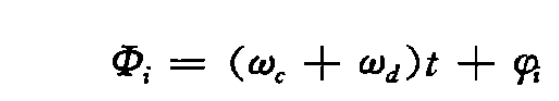

phi = pi;%假设相位跳变180°

## 7.计算回波

### 计算亮点模型的转移函数

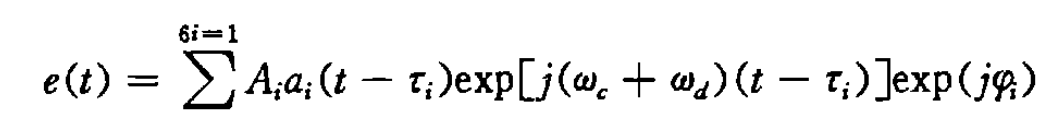

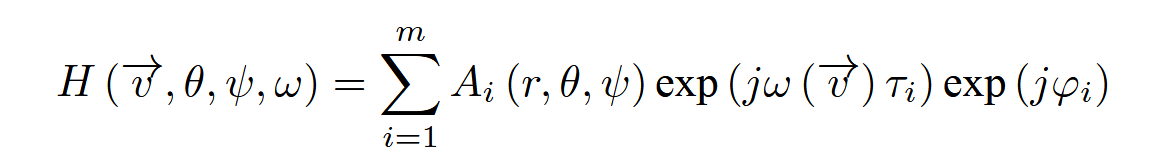

此公式为亮点模型的转移函数，将之前的计算带入

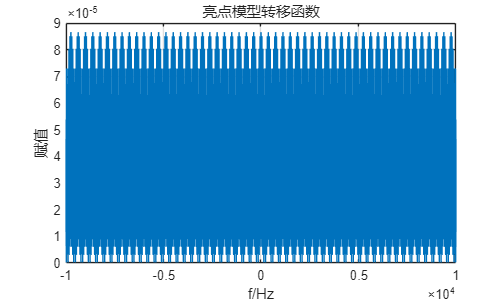

highlightTF = zeros(6,N);
temp = zeros(1,N);
for i = 1:6
    highlightTF(i,:) = A(i)*exp(-1j*(2*pi*f)*tauHighLight(i)).*exp(1j*phi);
end
TF2 = sum(highlightTF,1);
figure
plot(f,abs(TF2));xlabel('f/Hz');ylabel('赋值');grid on;title('亮点模型转移函数');
axis(-fs/2,fs/2,-inf,inf);

PAfterRef = ifft(fftshift(fft(P)).*TF2);
for i = 1:6
    PRef(i,:) = ifft(fftshift(fft(P)).*highlightTF(i,:));
end

各个部位亮点的回波

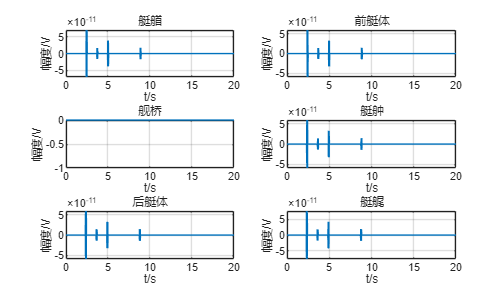

helpViewEveryPart(PRef,t,[0,20,-inf,inf]);

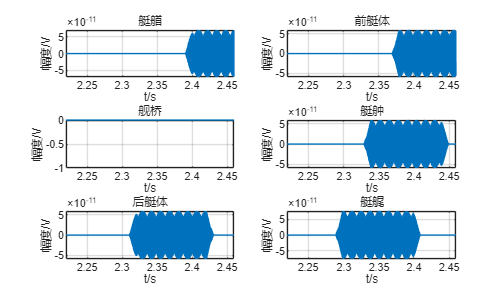

helpViewEveryPart(PRef,t,[2.2197,2.4597,-inf,inf]);

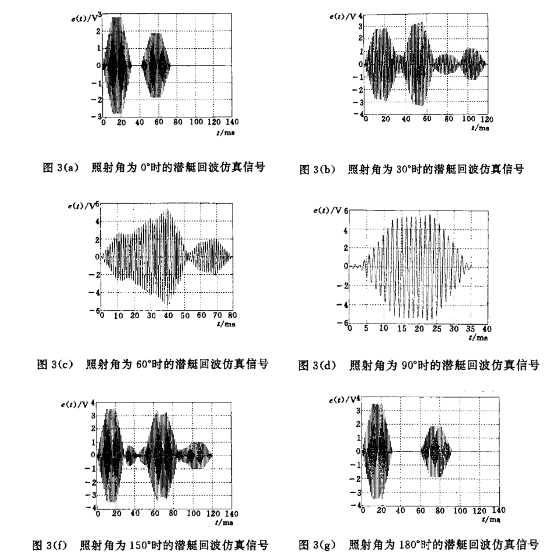

潜艇的回波

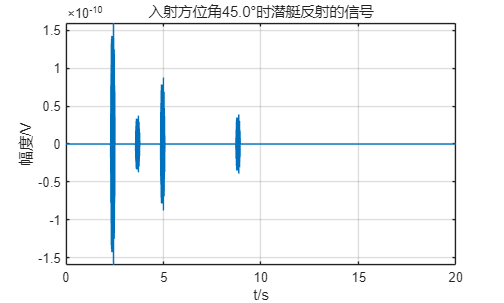

figure
plot(t,real(PAfterRef));xlabel('t/s');ylabel('幅度/V');grid on;
title(sprintf('入射方位角%.1f°时潜艇反射的信号', theta));axis([0,20,-inf,inf]);

e = PAfterRef;

## 8.信号返回发射点：

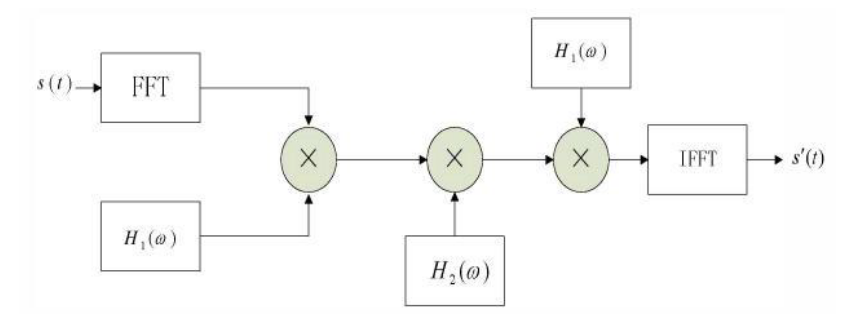

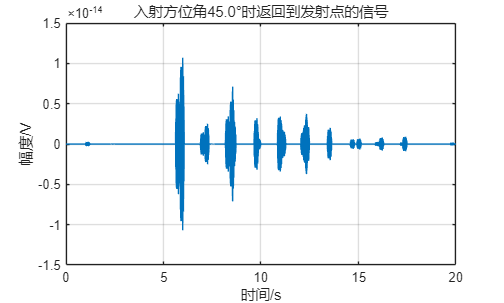

eAfterChan = ifft((fftshift(fft(e)).*TF1));
figure
plot(t,real(eAfterChan));xlabel('时间/s');ylabel('幅度/V');grid on;
title(sprintf('入射方位角%.1f°时返回到发射点的信号', theta));

s = eAfterChan;%交换变量

## 9.计算目标强度：

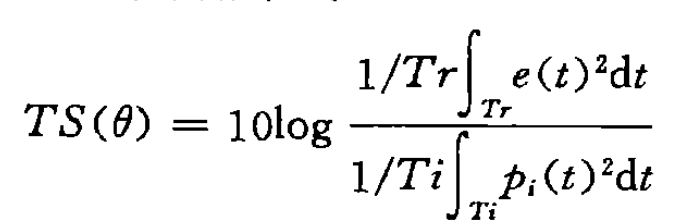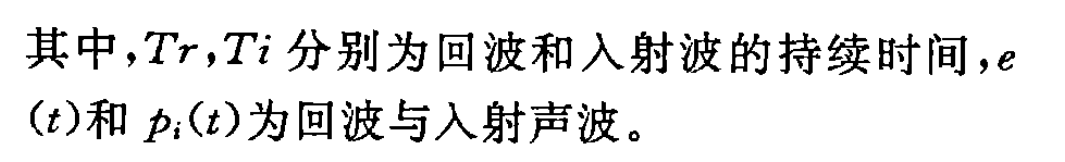

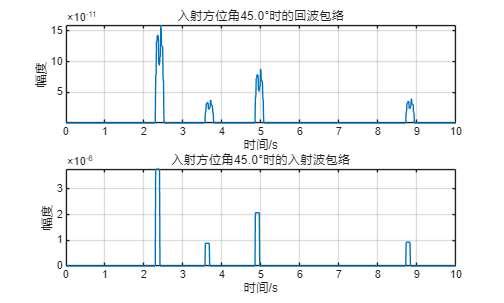

%根据回波的包络计算脉宽

figure
%回波包络
subplot(2,1,1)
plot(t, abs(e));
xlabel('时间/s');ylabel('幅度');title(sprintf('入射方位角%.1f°时的回波包络', theta));
axis([0,10,-inf,inf]);grid on;
%入射波包络
subplot(2,1,2)
plot(t, abs(P));
xlabel('时间/s');ylabel('幅度');title(sprintf('入射方位角%.1f°时的入射波包络', theta));
axis([0,10,-inf,inf]);grid on;

% %计算回波脉宽
% start_index_echo = find(abs(e) > 0, 1, 'first');%应该设置一个阈值
% end_index_echo = find(abs(e) > 0, 1, 'last');
% W_echo = (t(end_index_echo) - t(start_index_echo));
% fprintf('回波脉宽为：%.10f s\n', W_echo);

回波脉宽为：19.9999500000 s


% %入射波为32ms
% fprintf('入射波波脉宽为：%.3f s\n', width);

入射波波脉宽为：0.100 s


% %分子项
% TS_submarine = 10*log10(  ( sum(real(e).^2)/W_echo ) /     (  sum(real(P).^2)/width  )     );
% fprintf('入射信号为%d° 时目标强度为：%.3f dB\n', theta,TS_submarine);

入射信号为45° 时目标强度为：-110.123 dB
